clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


% Adjusts the A matrix as described in Examination 1
for i=1:4
    param.model.A(3*i,3*i) = -1;
end

## Design Procedure 1

param = control.DesignProcedure1(param,0);

Evaluation of design procedure 1 
Q is positive definite


ans =     0.2880    0.2892    0.2892    0.2892    0.7270    0.7275    0.7275    0.7275    1.3453    1.3453    1.3453    1.3493


R is positive definite


ans =    27.1436   37.5516   43.0021  114.6580  115.4977  115.6633  118.6280  124.1419  242.7167  318.9311  367.7529  952.4013


Gamma is found to be:


ans = 85.5366

Eigenvalues of the decoupled systems are all negative 


ans =   -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i  -1.3274 + 3.8404i  -1.3274 - 3.8404i  -0.9221 + 0.0000i  -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i  -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7753 + 5.2359i  -0.7753 - 5.2359i  -0.4258 + 5.9406i  -0.4258 - 5.9406i  -0.3169 + 6.1623i  -0.3169 - 6.1623i  -0.2890 + 6.1948i  -0.2890 - 6.1948i  -0.9280 + 0.0000i  -0.9296 + 0.0000i  -0.9297 + 0.0000i  -0.9300 + 0.0000i


-4.614474, 0.000000, 0.000000, 0.000000, 
-4.614474, -0.000000, -0.000000, 0.000000, 
-4.614473, -0.000000, -0.000000, 0.000000, 
-4.614473, 0.000000, 0.000000, 0.000000, 
-4.614469, -0.000000, 0.000000, 0.000000, 
-4.614472, 0.000000, 0.000000, -0.000000, 
-4.614473, -0.000000, 0.000000, 0.000000, 
-4.614620, 0.000000, 0.000000, 0.000000, 
-4.614600, 0.000000, -0.000000, 0.000000, 
-4.614533, 0.000000, 0.000000, 0.000000, 
-4.614563, 0.000000, 0.000000, 0.000000, 
-254.198930, 0.000000, -0.000000, 0.000000, 
-9134.033748, 0.000000, 0.000000, -0.000000, 
-46963.894040, -0.000274, -0.000006, -0.000007, 


-69577.371881, 3.155063, 3.147582, 3.150014, 


-69577.371881, 3.155063, 3.147582, 3.150014, 


-69577.371995, 3.155063, 3.147582, 3.150013, 


-69577.371881, 3.155063, 3.147582, 3.150014, 


-69577.371881, 3.155063, 3.147582, 3.150014, 


-69577.371881, 3.155063, 3.147582, 3.150014, 


-69577.371881, 3.155063, 3.147582, 3.150014, 
-0.000000, 0.000000, 0.000000, -6049334.065948, 
-38529.861434, 0.000000, 0.000000, -0.000000, 
-70909.442768, -0.000000, -0.000000, 0.000000, 
-70341.215482, -0.001800, -0.000039, -0.000042, 
-65746.723130, -30384.854388, 0.000000, 0.000000, 
-72710.805614, -0.000357, -0.000008, -0.000008, 


-73247.187909, 5.985148, 5.962366, 5.969785, 
-70797.537907, 0.000000, 0.000000, 0.000000, 
0.000000, -5926.416056, -0.000000, 0.000000, 
-72503.742126, -4683.240439, 0.000000, 0.000000, 
-77071.841208, -0.000000, 0.000000, 0.000000, 
0.000000, -3869.722588, 0.000000, 0.000000, 
-78960.110854, 0.000000, -0.000000, 0.000000, 
-78572.067707, 0.000000, 0.000000, 0.000000, 
-78778.348146, 0.000000, 0.000000, 0.000000, 
-77922.389446, 0.000000, 0.000000, 0.000000, 
-77293.841075, 0.000000, -0.000000, 0.000000, 
-77286.106847, 0.000000, 0.000000, 0.000000, 
-81240.673082, 0.000000, 0.000000, 0.000000, 
-81240.673082, 0.000000, 0.000000, 0.000000, 
-81240.673084, 0.000000, 0.000000, 0.000000, 
-81240.673082, 0.000000, 0.000000, 0.000000, 
-81240.673082, 0.000000, 0.000000, -0.000000, 
-81240.673082, 0.000000, 0.000000, 0.000000, 
-81240.673073, 0.000000, -0.000000, 0.000000, 
-81240.673080, 0.000000, 0.000000, -0.000000, 
-81240.673079, 0.000000, 0.000000, -0.000000, 
-81240.673082, 0.000000,

-227578.838281, 0.000000, -0.000000, -0.000000, 
-246944.644252, 0.000000, 0.000000, -0.000000, 
-246944.644252, 0.000000, 0.000000, -0.000000, 
-246944.644255, -0.000000, -0.000000, 0.000000, 
-246944.644252, 0.000000, 0.000000, 0.000000, 
-246944.644253, -0.000000, -0.000000, 0.000000, 
-246944.644252, 0.000000, 0.000000, -0.000000, 
-246944.644265, 0.000000, -0.000000, 0.000000, 
-246944.644255, -0.000000, 0.000000, 0.000000, 
-246944.644257, 0.000000, 0.000000, -0.000000, 
-246944.644252, 0.000000, 0.000000, -0.000000, 
-246944.645709, 0.000000, -0.000000, 0.000000, 
-246944.644252, 0.000000, 0.000000, -0.000000, 
-246944.644252, 0.000000, 0.000000, 0.000000, 
-246944.644252, 0.000000, 0.000000, -0.000000, 
-246960.129990, 0.000000, 0.000000, 0.000000, 
-246975.606481, 0.000000, -0.000000, 0.000000, 
-246975.606481, 0.000000, -0.000000, 0.000000, 
-246975.606483, -0.000000, -0.000000, -0.000000, 
-246975.606481, -0.000000, -0.000000, 0.000000, 
-246975.606482, 0.000000, 0.000000, 0

-242286.187909, 0.000000, 0.000818, 0.000032, 
0.000000, -86580.984743, 0.000000, 0.000000, 
0.000000, -71379.665507, -0.000000, -0.000000, 
0.000000, -71379.665507, -0.000000, -0.000000, 
0.000000, -71379.665524, 0.000000, 0.000000, 
0.000000, -71379.665509, -0.000000, 0.000000, 
0.000000, -71379.665511, 0.000000, -0.000000, 
0.000000, -71379.665507, -0.000000, -0.000000, 
0.000000, -71379.665496, 0.000000, 0.000000, 
0.000000, -71379.665488, -0.000000, -0.000000, 
0.000000, -71379.665507, -0.000000, -0.000000, 
0.000000, -71379.664574, 0.000000, 0.000000, 
0.000000, -71379.665507, 0.000000, -0.000000, 
0.000000, -71379.665513, -0.000000, -0.000000, 
0.000000, -71379.665507, -0.000000, -0.000000, 
-246403.982516, 0.000000, 0.000000, 0.000000, 
-246403.982516, 0.000000, 0.000000, 0.000000, 
-246403.982517, 0.000000, 0.000000, 0.000000, 
-246403.982516, 0.000000, 0.000000, 0.000000, 
-246403.982511, 0.000000, -0.000000, 0.000000, 
-246403.982516, 0.000000, 0.000000, 0.000000, 
-246403.9

0.000000, -14653.209079, -0.000000, 0.000000, 


0.000000, -14653.209081, 0.000000, -0.000000, 


0.000000, -14653.209076, -0.000000, 0.000000, 


0.000000, -14653.209060, -0.000000, 0.000000, 


0.000000, -14653.209049, -0.000000, 0.000000, 
-416584.165522, -30884.564110, -0.000000, 0.000000, 
0.000000, -26807.627519, 0.000000, -0.000000, 
-413801.469116, 0.000000, 0.000000, 0.000000, 
0.000000, -44418.555131, 0.000000, 0.000000, 
0.000000, -44418.555131, 0.000000, -0.000000, 
0.000000, -44418.555156, 0.000000, -0.000000, 
0.000000, -44418.555134, 0.000000, -0.000000, 
0.000000, -44418.555136, 0.000000, 0.000000, 
0.000000, -44418.555131, 0.000000, -0.000000, 
0.000000, -44418.555005, 0.000000, -0.000000, 
0.000000, -44418.555115, -0.000000, -0.000000, 
0.000000, -44418.555104, 0.000000, -0.000000, 
-413521.175060, 0.000000, 0.000000, -0.000000, 
0.000000, -44418.555132, -0.000000, -0.000000, 
0.000000, -44418.555142, -0.000000, 0.000000, 
-440821.718531, -0.000000, 0.000000, 0.000000, 
0.000000, -44418.555131, 0.000000, 0.000000, 
-409276.304574, 0.000000, -0.000000, 0.000000, 
-383348.145352, 0.000000, 0.000000, 0.000000, 
-420848.424775, 0.000000, 0.000000, -0.000000, 
-354

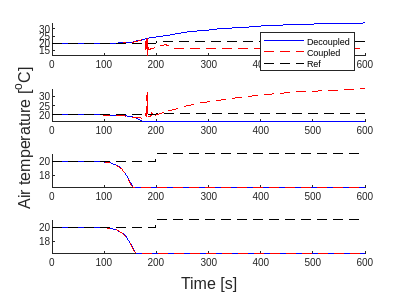

util.SimulateStep(param,"Examination_Examination1_DP1",0);

## Design procedure 2

param = control.DesignProcedure2(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.1117    0.1126    0.1126    0.1127    0.4601    0.4602    0.4604    0.4607    2.4021    2.4084    2.4232    2.4356


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =    -4.1399   -0.0690   -1.0312   -4.1994   -0.0748   -1.0354   -4.1658   -0.0764   -1.0369   -4.1471   -0.0708   -1.0327


Eigenvalues of the coupled systems are all negative 


ans =    -4.2658   -4.3191   -4.3865   -4.4131   -0.0986   -0.1108   -0.1220   -0.1274   -1.0581   -1.0704   -1.0804   -1.0859


-5.929974, 0.000000, -0.000000, 0.000000, 
-13.906347, -0.000000, -0.000000, -0.000000, 
0.000000, -1.284307, 0.000000, 0.000000, 
-17.316318, -4.415204, 0.000000, 0.000000, 


0.000000, -13.483069, -0.000000, -0.000000, 
0.000000, -29.086387, -0.000000, 0.000000, 
0.000000, -48.910523, -0.000000, 0.000000, 
0.000000, -48.910523, -0.000000, 0.000000, 


0.000000, -48.910523, -0.000000, -0.000000, 


0.000000, -48.910523, 0.000000, -0.000000, 
0.000000, -48.910523, 0.000000, -0.000000, 
0.000000, -48.910523, -0.000000, 0.000000, 
0.000000, -48.910523, -0.000000, -0.000000, 
0.000000, -48.910523, -0.000000, 0.000000, 
0.000000, -48.910523, -0.000000, 0.000000, 
-28.523052, -50.578854, -0.000000, 0.000000, 
0.000000, -48.910533, -0.000000, -0.000000, 
0.000000, -48.910523, -0.000000, 0.000000, 


0.000000, -100.029183, 0.000000, 0.000000, 
0.000000, -101.470086, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196212, -0.000000, -0.000000, 
-91.004588, -231.196212, 0.000000, 0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, 0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-91.004603, -231.196252, -0.000000, 0.000000, 
-91.004602, -231.196248, 0.000000, 0.000000, 
-91.004588, -231.196213, 0.000000, -0.000000, 
-167.596092, -425.776137, -0.000000, -0.000000, 
-167.596092, -425.776137, -0.000000, -0.000000, 
-167.596092, -425.776137, -0.000000, -0.000000, 
-167.596092, -425.776137, 0.000000, 0.000000, 
-167.596092, -425.776137, -0.000000, -0.000000, 
-167.596092,

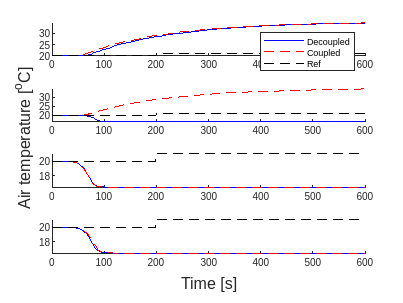

util.SimulateStep(param,"Examination_Examination1_DP2",0);